clear;
num = 500;
m = 3;
n = 3;
E = abs(randn(m, n));
R = abs(randn(num, m));
R = R ./ sum(R, 2);
V = R * E;

c = 3;
X = ones(num, n+1) * c;
X(:, 1:end-1) = V;
S = X(1:m, :);
A = abs(randn(num, m));

a = 1e-2;
b = 1e-1;
for i = 1:50000
    S_ = S;
    S_(:, end) = 0;
    dA = (A * S - X) * S';
    dS = A' * (A * S - X) + b * det(S_*S_') * pinv(S_*S_') * S_;
    
    A = A - a * dA;
    S = S - a * dS;
    A(A < 0) = 0;
    S(S < 0) = 0;
    
    S(:, end) = c;
end
vol = det(S_*S_');
error = mean(mean((X - A * S).^2));

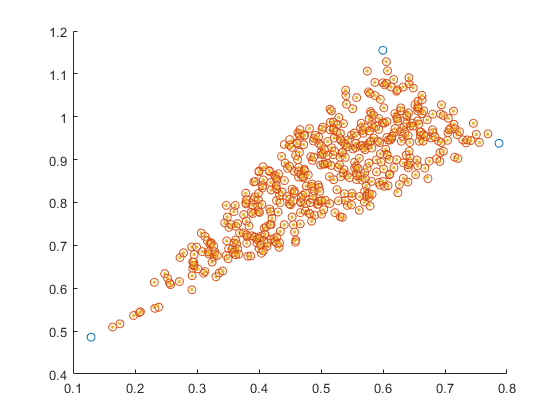

X_ = A * S;
figure, hold on;
scatter3(S(:, 1), S(:, 2), S(:, 3));
scatter3(X(:, 1), X(:, 2), X(:, 3), [], 'o');
scatter3(X_(:, 1), X_(:, 2), X_(:, 3), [], '.');
hold off;